Q7

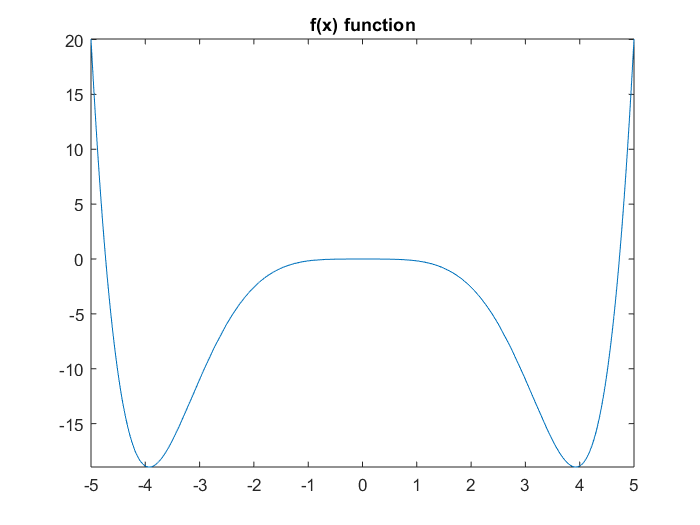

format long
syms f(x)

% the function to be solved 
f(x) = cos(x)*cosh(x)-1;

% the threshold used for the relative error
thresh = 10^-4;

% display function to visualize zeros
fplot(f(x))
title('f(x) function')

% find the value of the real root to calculate relative error
p = @(x) cos(x)*cosh(x)-1;
actual = fzero(p,[4, 5])

actual =    4.730040744862704


% continue until it finds the root
root = 0;
% set the step size
h = 0.5;
% since we don't want to catch the point at 0 we start after it
i = 0.51;
while 1
    % we know there is a root if there is a sign change in between points
    if f(i)*f(i-h) < 0
        x_n  = i;
        x_1 = i-h;
        % check to see if root is within the relative error accepted by thresh
        while abs(x_n - x_1)/x_1 > thresh
            % calculate the change in x at each iteration
            dx = (f(x_n)*(x_n-x_1)/(f(x_n)-f(x_1)));
            x_1 = x_n;
            
            % calculate the new x
            x_n = x_n - dx;
        end        
        root = x_n;
        break;
    end
    i = i + h;
end

% display the value
relativeError = double(abs(root - actual)/actual)

relativeError =      1.786830646479475e-09


root = double(root)

root =    4.730040736410922
